# Ejemplo de Discretización de Función de Transferencia


$$\textrm{Gp}\left(s\right)\longrightarrow \textrm{Gp}\left(z\right)$$



$$\textrm{Gp}\left(z\right)=\left(1-z^{-1} \right)Z\left\lbrace \frac{\textrm{Gp}\left(s\right)}{s}\right\rbrace$$


#### Ej 1

clear all
s=tf('s');
Gps = .5*s / (3*s^2 + .5*s + 2)

Gps =
 
        0.5 s
  -----------------
  3 s^2 + 0.5 s + 2
 
Continuous-time transfer function.
Model Properties


T=0.5;
z=tf('z',T);
% Gpz = 1/8 - (z-1)/(z-exp(-T(i))) + 2.75*(z-1)/(z-exp(-2*T(i))) - 1.875*(z-1)/(z-exp(-4*T(i)))
% Gpz = 2 * (z^(-3 / T(i))) * (1 - (z - 1) / (z - exp(-T(i) / 9)))
Gpz = (z-1) / (sqrt(95) * 1i * (z - exp((1i*sqrt(95) - 1)*T/12))) - (z-1) / (sqrt(95) * 1i * (z - exp(-(1i*sqrt(95) + 1)*T/12)))

Gpz =
 
      7.387 z - 7.387
  -----------------------
  95 z^2 - 167.4 z + 87.4
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


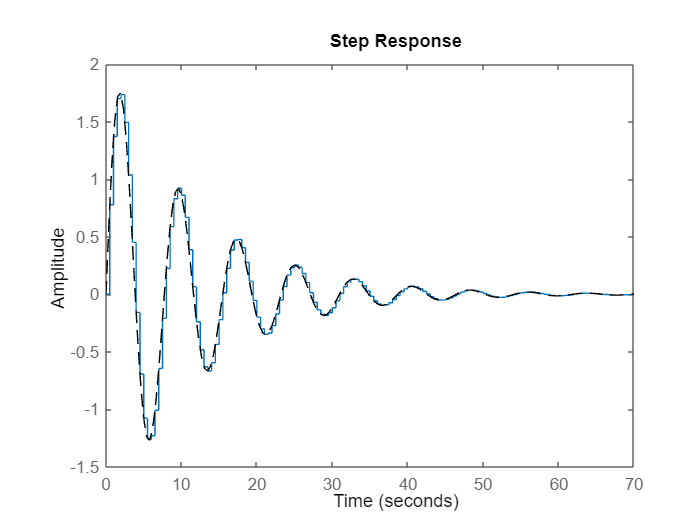

step(10*Gpz)
hold on
step(10*Gps,'k--')